clear, clc

## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

### Example: slider crank

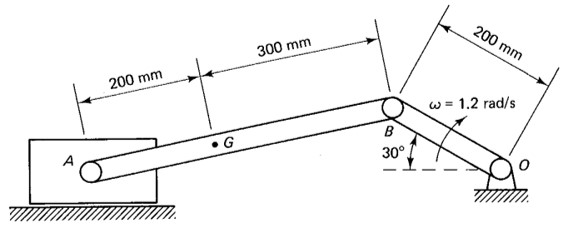

Body numbering

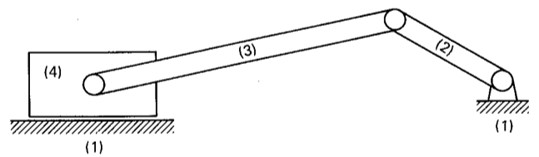

Local coordinate frames

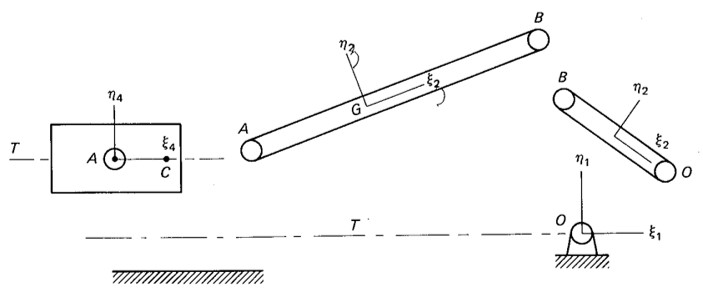

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

mbs = init_mbs();

Unrecognized function or variable 'init_mbs'.

mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30));
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15));
mbs = add_body(mbs, "slider", -0.6)

### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

% Revolute joints
mbs = add_revolute(mbs, "revO", "ground", [0; 0], "crank", [0.1, 0.0]);
mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Prismatic joints

mbs = add_prismatic(mbs, "linA", "slider", [0; 0], [0.05; 0], "ground", [0.0, 0.0]);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

% mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
% mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
om = 1.2; % rad/s
mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), mbs.nq)
fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))
fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))
fprintf("In total %d DOF are constrained!\n", mbs.nc)

### **Coordinates (initial values)**

They vere defined in the mbs.bodies. We want to put them together in single vector.

q0 = initial_position(mbs);

### Constraints vector C

t0 = 0.0;
C = constraints(mbs, q0, t0);

### Solution using fsolve

Now we can check the code with function fsolve

tic
q0_correct = fsolve(@(y)constraints(mbs, y, 0.0), q0);
toc
% disp([q0, q0_correct])
C0 = constraints(mbs, q0_correct, t0)

### Jacobian of constraints

We need it for position and velocity analysis (and we will need it for euqations of motion).

Cq = constraints_dq(mbs, q0);

Now we can solve kinematic analysis on position (initial) using Newton-Raphson

tic
[q0_correct_NR, NR_iter] = ...
    NR_method(@(y)constraints(mbs, y, 0.0), ...
    @(y)constraints_dq(mbs, y), q0, 1e-8)
toc

Simple check

disp([q0, q0_correct, q0_correct_NR])
C0_NR = constraints(mbs, q0_correct_NR, t0)

### Kinematic analysis

mbs = add_gravity(mbs, [0, -9.81]); % Adding graviti to compute acceleration
h = 0.05;
t_end = 1;
tol = 1e-8;
[T, Q, Qp, Qpp, niter] = kinematic_analysis(mbs, q0, h, t_end, tol);

Very basic postprocessing

plot(Q(:, 4), Q(:, 5), Q(:, 7), Q(:, 8), ...
    Q(:, 10), Q(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on position')

Now similar plot for velocity

plot(Qp(:, 4), Qp(:, 5), Qp(:, 7), Qp(:, 8), ...
    Qp(:, 10), Qp(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on velocity')

And similar plot for acceleration

figure_kinematic_analysis_acceleration = figure;
plot(Qpp(:, 4), Qpp(:, 5), Qpp(:, 7), Qpp(:, 8), ...
    Qpp(:, 10), Qpp(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on acceleration')
saveas(figure_kinematic_analysis_acceleration, 'figure_kinematic_analysis_acceleration.png');

Number of NR iterations

plot(niter)